# 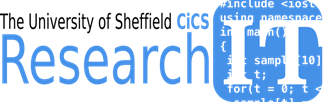                                      

# **Matlab Fundamentals**

# Introduction

### Learning Outcomes

- Manipulate data sets using Matrices, Tables, Cell Arrays and Structures

# Preliminaries

### Vectors and Matrices

Manual entry array of an array, using the [] bracket notation

- columns separated with a space

- rows separated by a ;

%x= % 1x3 row vector elements separated with spaces
x=[1 2 3]
%y=[] %2x1 matrix  column vector elements separated by ;
y=[sqrt(10); pi^2; sin(pi/4)]
%z=[]  % 2x3 matrix
z=[4 5 6; 7 8 9]

Convert row vector to column vector using transpose ' operator

xt=x'
%

Functions to define array using linspace and the colon notation

u=zeros(2,2);
v=eye(3,3);
w=ones(4,4);
x1=linspace(1,10,5);
y1=(1:1:10);
z1=rand(5,1);
 % linspace(first,last,number of elements)
 %note using transpose


Inspect the work space

 % who list of variables
 who

 % whos list showing properties
 
 whos

### Array operations

We use the [] brackets to assign elements in the array.

The () brackets are used extract elements which we demonstrate below

First create a 6x4 matrix of random numbers.

data=100*rand(6,4)

%x1= %extract  a specific element
x1=data(2,2)

Note below the use of the end keyword

%x2= %get item  at row 6  and column 2
x2=data(end,2)
x3=data(end-1,end-2)


### Extracting multiple elements

Create a row vector from the data set

x3=data(2,:)%


Create a column vector from the data set

x4=data(2:end-1,2)%

Change values in the array, first create a sub array

v1=data(:,end-1:end)
v1(1,2)=10
v1


change one element of v1

%v1();%
%v1();%
x5=v1(1:end,2)
x5r=v1(end:-1:1,2) % array in reverse

### Operations on Matrices

vr=round(10*x3)
[vmax,loc]=max(data)


Look at the behaviour of the multiply operation, we use a simple row and column vector to illustrate

row=[1 2 3]
col=[4;5;6]
row*col
col*row
col.*row
row.*col

Now try a matrix multiply, a pair of simple square matrices clearly illustrates correct matrix multiplication and the behaviour of the dot operator i.e. element wise operation

m1=[1 2; 3 4]
m2=[2 0; 0 2]

m2*m1

m2.*m1

### Multiple Output Function Calls

Multiple outputs are normally returned as a row vector (comma or space separated elements). Functions may also return data as a cell array which we will see later.

numd=numel(data)

%size of data
dsize=size(data)
%numrows, numcols
[numrows,numcols]=size(data)

%maximum and index of maximum of data
[maxd,idmax]=max(data)

A particularly useful function is the reshape function.

Example create a row vector of 16 values and reshape to a 3x4 matrix

rv=1:12
%rmat reshape rv as 3x4
rmat=reshape(rv,[3,4])

Clear the workspace and the variables

clear('u') %clear specific variable note use of quotes
clear %clear the workspace
%clear all to clear the whole workspace
%clc %clear the command window

x=round(20*rand(3,3));
y=round(20*rand(3,3));
